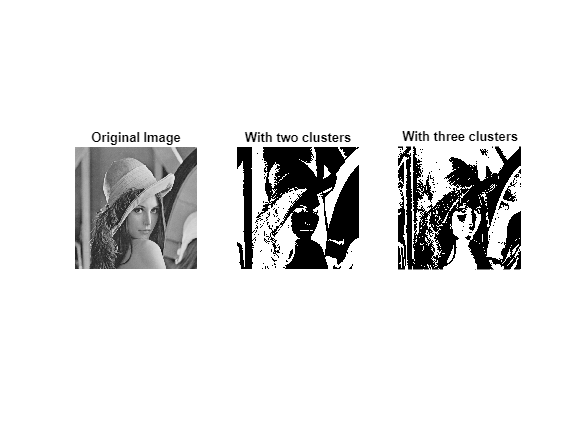

clc;
clear all;

img1 = imread('lena_gray.jpeg');

[numr, numc] = size(img1);
figure;
subplot(1,3,1);
imshow(img1);
title('Original Image');
subplot(1,3,2);

nc = 2;
ci = kmeans(double(img1(:)), nc);

B = zeros(size(ci));
B(ci==2) = 255;
C = im2bw(B);

S = reshape(C, numr, numc);
imshow(S);
title('With two clusters');
subplot(1,3,3);

nc = 3;
ci = kmeans(double(img1(:)), nc);

B = zeros(size(ci));
B(ci==3) = 255;
C = im2bw(B);
S = reshape(C, numr, numc);
imshow(S);
title('With three clusters');